# DC Motor Transfer Function Estimation

Open serial port.

clear s % closes ports already open
s = serialport('COM11',9600) % Check COM#11

s =   Serialport with properties:

                 Port: "COM11"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


Read serial port values and parse data into lists. 

values = 220;
t = zeros(1, values);
pos = zeros(1, values);
spd = zeros(1, values);
inpt = zeros(1, values);

% loop through all 
for n = 1:values
    msg = s.readline();
    items = split(msg, ',');
    vals = arrayfun(@str2num, items);
    t(n) = vals(1);
    pos(n) = vals(2);
    spd(n) = vals(3);
    inpt(n) = vals(4);
end

% save lab2_10292024.mat t pos spd inpt

% load lab2_10292024.mat

Calculate steady state value, steady state gain, and time constant. 

Omega_ss = mean(spd(end-14:end)) % steady state speed

Omega_ss = 61.7376

SSG = Omega_ss / 3 % steady state gain Fv/M M=3 (3V input)

SSG = 20.5792


[SPD, ia, ic] = unique(spd); % grab only unique values of spd
tau = interp1(SPD, t(ia), 0.63 * Omega_ss) % calculate time at 0.63 * Omega_ss

tau = 0.3053

Calculate settling time 

i = find(spd >= 0.98 * Omega_ss);

T_s = t(i(1))

T_s = 1.2730

Calculate a & b of transfer function

a = 1/tau

a = 3.2751

b = SSG * a

b = 67.3999

Plot speed, angle and input voltage with respect to time. 

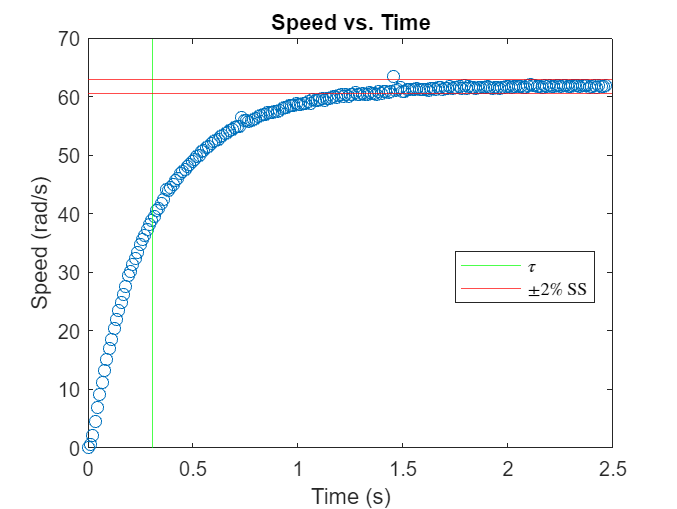

% plot speed
plot(t,spd, 'o')
xline(tau, 'g')
yline(0.98 * Omega_ss, 'r')
yline(1.02 * Omega_ss, 'r')
title("Speed vs. Time")
xlabel("Time (s)")
ylabel("Speed (rad/s)")
legend({'', '$\tau$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','best') 

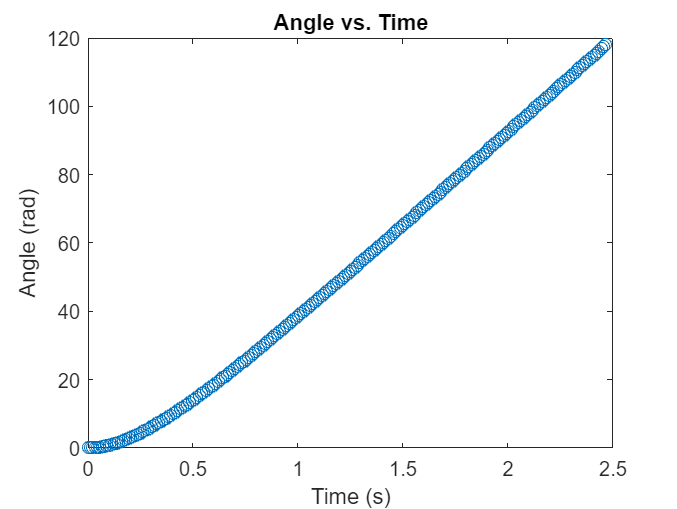


% plot angle
plot(t,pos, 'o')
title("Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (rad)")

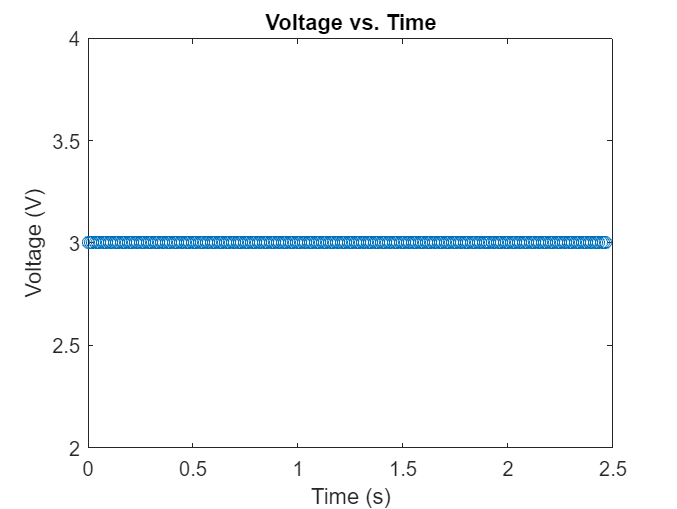


% plot input voltage
plot(t,inpt, 'o')
title("Voltage vs. Time")
xlabel("Time (s)")
ylabel("Voltage (V)")